## Task 5.9: PhantomX Pincher Digital Twin

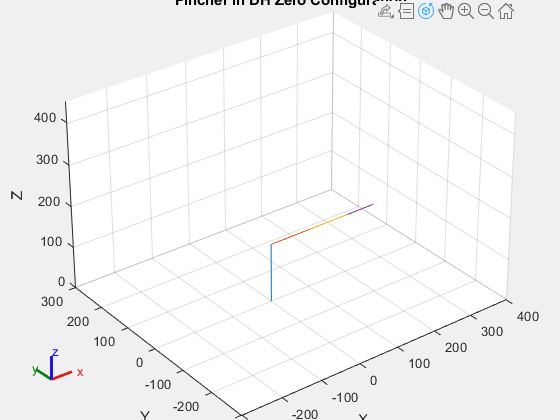

Unable to resolve the name 'pincher.BodyNames'.

clear; clc; close all;

pincher = rigidBodyTree('DataFormat', 'row');

a2 = 103; a3 = 102; a4 = 71;
d1 = 141;

% --- Link 1 (Base) ---
body1 = rigidBody('link1');
jnt1 = rigidBodyJoint('joint1', 'revolute');
setFixedTransform(jnt1, [0, pi/2, d1, 0], 'dh');
body1.Joint = jnt1;
addBody(pincher, body1, 'base');

% --- Link 2 (Shoulder) ---
body2 = rigidBody('link2');
jnt2 = rigidBodyJoint('joint2', 'revolute');
setFixedTransform(jnt2, [a2, pi, 0, 0], 'dh');
body2.Joint = jnt2;
addBody(pincher, body2, 'link1');

% --- Link 3 (Elbow) ---
body3 = rigidBody('link3');
jnt3 = rigidBodyJoint('joint3', 'revolute');
setFixedTransform(jnt3, [a3, 0, 0, 0], 'dh');
body3.Joint = jnt3;
addBody(pincher, body3, 'link2');

% --- Link 4 (Wrist) ---
body4 = rigidBody('link4');
jnt4 = rigidBodyJoint('joint4', 'revolute');
setFixedTransform(jnt4, [a4, 0, 0, 0], 'dh');
body4.Joint = jnt4;
addBody(pincher, body4, 'link3');


eeBody = rigidBody('end_effector');
% Fixed joint by default, no transform needed since it sits exactly at the end of Link 4
setFixedTransform(eeBody.Joint, eye(4)); 
addBody(pincher, eeBody, 'link4');

figure('Name', 'PhantomX Pincher Digital Twin', 'NumberTitle', 'off');

show(pincher,deg2rad([0, 0, 0, 90]) ); 
title('Pincher in DH Zero Configuration');
view(3);
axis([-300 400 -300 300 0 450]);